Variational Gaussian Process

takes a mean function a kernel object and a list of inducing points

Training uses a mini-batch stochastic optimization.

clear all
%close all
clc

f1 = @(x) (6*x-2).^2.*sin(12*x-4);

xx = linspace(0,1,100)';
yy = f1(xx);

x1 = lhsdesign(500,1);
y1 = f1(x1);
y1 = y1 + normrnd(0,0*y1 + 0.8);

ma = means.const(2);%+means.linear(6)
a = kernels.Matern52(1,0.2);%*kernels.EQ(1,0.4).periodic(1,2) + kernels.RQ(0.1,0.3);

a.signn = 0.5;

Z = VGP(ma,a,linspace(0,1,5)');

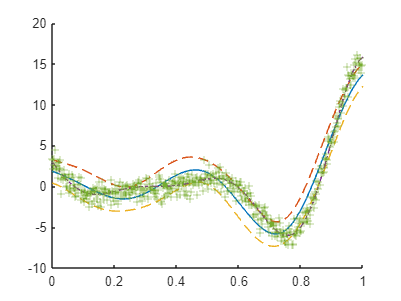

Z1 = Z.condition(x1,y1);

[ys,sig] = Z1.eval(xx);

figure
hold on
plot(xx,ys)
plot(xx,ys+2*sqrt(sig),'--')
plot(xx,ys-2*sqrt(sig),'--')
plot(xx,yy,'-.')
plot(x1,y1,'+')

tic
[Z2,LL] = Z1.train();

Variables (index) internally transformed to log coordinates: [2 3].
Beginning optimization of a STOCHASTIC objective fcn.

Optimization terminated: mesh size less than OPTIONS.TolMesh.
Estimated function value at minimum: 169.65 +/- 95.663 (mean +/- SEM from 10 samples).

Variables (index) internally transformed to log coordinates: [2 3].
Beginning optimization of a STOCHASTIC objective fcn.

Optimization terminated: mesh size less than OPTIONS.TolMesh.
Estimated function value at minimum: 35.0374 +/- 3.09898 (mean +/- SEM from 10 samples).

Variables (index) internally transformed to log coordinates: [2 3].
Beginning optimization of a STOCHASTIC objective fcn.

Optimization terminated: mesh size less than OPTIONS.TolMesh.
Estimated function value at minimum: 64.6447 +/- 22.6141 (mean +/- SEM from 10 samples).



toc

Elapsed time is 17.464392 seconds.


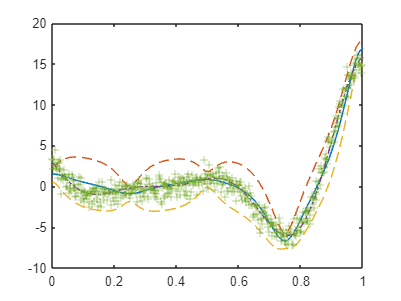

[ys,sig] = Z2.eval(xx);

figure
plot(xx,ys)
hold on
plot(xx,ys+2*sqrt(sig),'--')
plot(xx,ys-2*sqrt(sig),'--')
plot(xx,yy,'-.')
plot(x1,y1,'+')


for i = 1:5
    xn = bads(@(x) Z2.newXuDiff(x),rand(),0,1);
    Z2 = Z2.addInducingPoints(xn);
end

Beginning optimization of a DETERMINISTIC objective fcn.
 Iteration    f-count         f(x)           MeshScale          Method          Actions
     0           2        -2.60579               1                              Uncertainty test
     0           3        -3.84447               1            Initial mesh      
     1           4         -26.585               1         Successful poll      Train (failed)
     2           7         -26.585             0.5             Refine grid      
     3          11         -26.585            0.25             Refine grid      
     4          14        -26.6256            0.25    Incremental search (ES-wcm)      
     4          15        -26.6256           0.125             Refine grid      Train
     5          16        -26.7128           0.125    Successful search (ES-wcm)      
     5          17        -26.7159           0.125    Incremental search (ES-ell)      
     5          18        -26.7161           0.125    Incremental searc

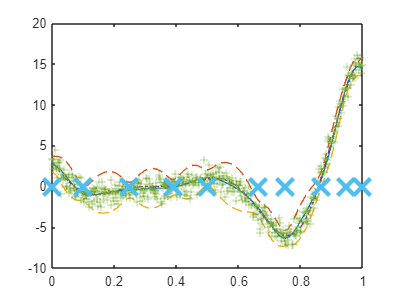


[ys,sig] = Z2.eval(xx);

figure
plot(xx,ys)
hold on
plot(xx,ys+2*sqrt(sig),'--')
plot(xx,ys-2*sqrt(sig),'--')
plot(xx,yy,'-.')
plot(x1,y1,'+')
plot(Z2.Xu,0*Z2.Xu,'x','MarkerSize',18,'LineWidth',3)

tic
[Z3,LL] = Z2.train();

Variables (index) internally transformed to log coordinates: [2 3].
Beginning optimization of a STOCHASTIC objective fcn.

Optimization terminated: mesh size less than OPTIONS.TolMesh.
Estimated function value at minimum: 24.3669 +/- 0.617488 (mean +/- SEM from 10 samples).

Variables (index) internally transformed to log coordinates: [2 3].
Beginning optimization of a STOCHASTIC objective fcn.

Optimization terminated: mesh size less than OPTIONS.TolMesh.
Estimated function value at minimum: 28.6857 +/- 1.03839 (mean +/- SEM from 10 samples).

Variables (index) internally transformed to log coordinates: [2 3].
Beginning optimization of a STOCHASTIC objective fcn.

Optimization terminated: mesh size less than OPTIONS.TolMesh.
Estimated function value at minimum: 26.1591 +/- 0.589226 (mean +/- SEM from 10 samples).



toc

Elapsed time is 14.970007 seconds.


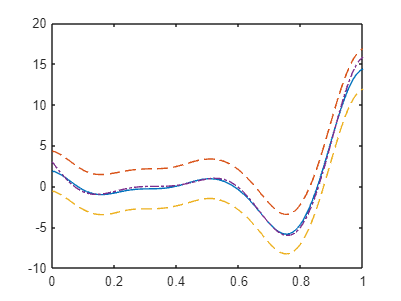


[ys,sig] = Z3.eval(xx);

figure
plot(xx,ys)
hold on
plot(xx,ys+2*sqrt(sig),'--')
plot(xx,ys-2*sqrt(sig),'--')
plot(xx,yy,'-.')